# Venus

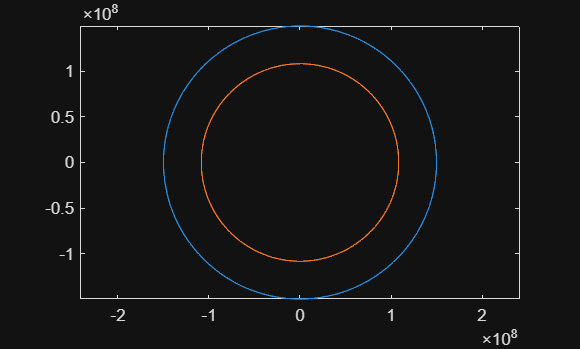

clear all, close all, clc, clf
r_Venus = 108208930;  % Mittlerer Bahnradius Venus  
r_Mars  = 227990000;  % Mittlerer Bahnradius Mars 
r_Erde  = 149597870;  % Mittlerer Bahnradius Erde

T_Venus = 224.701; % Tage
T_Erde = 365.256; % Tage
T_Mars = 686.980; % Tage

w_Venus = 2*pi / T_Venus;
w_Erde = 2*pi / T_Erde;

tspan = linspace(0,T_Erde,T_Erde);

x_Erde = r_Erde * cos(w_Erde .*tspan);
y_Erde = r_Erde * sin(w_Erde .*tspan);

x_Venus = r_Venus * cos(w_Venus .*tspan);
y_Venus = r_Venus * sin(w_Venus .*tspan);

figure;
plot(x_Erde,y_Erde);
hold on;
plot(x_Venus,y_Venus);
axis equal;